clear all
clf
T_0 = -5+273.15;
R_0 = 33900;
T_1 = 10+273.15;
R_1 = 17960;
T_2 = 25+273.15;
R_2 = 10000;
T_3 = 40+273.15;
R_3 = 5830;

syms A_0 A_1 A_2 A_3

eq1 = 1/T_0 == A_0 + A_1 * log(R_0) +  A_2 * log(R_0)^2 + A_3 * log(R_0)^3;
eq2 = 1/T_1 == A_0 + A_1 * log(R_1) +  A_2 * log(R_1)^2 + A_3 * log(R_1)^3;
eq3 = 1/T_2 == A_0 + A_1 * log(R_2) +  A_2 * log(R_2)^2 + A_3 * log(R_2)^3;
eq4 = 1/T_3 == A_0 + A_1 * log(R_3) +  A_2 * log(R_3)^2 + A_3 * log(R_3)^3;

[A0, A1, A2, A3] = vpasolve([eq1, eq2, eq3, eq4], [A_0,A_1,A_2,A_3], [-100, -100, -100, -100]);
A0 = double(vpa(A0,12))

A0_ = 5.1099e-04

A1 = double(vpa(A1,12))

A1 = 3.7172e-04

A2 = double(vpa(A2,12))

A2 = -1.2778e-05

A3 = double(vpa(A3,12))

A3 = 6.4413e-07


syms A_0 A_1 A_3

eq1 = 1/T_0 == A_0 + A_1 * log(R_0) + A_3 * log(R_0)^3;
eq2 = 1/T_1 == A_0 + A_1 * log(R_1) + A_3 * log(R_1)^3;
eq3 = 1/T_2 == A_0 + A_1 * log(R_2) + A_3 * log(R_2)^3;
eq4 = 1/T_3 == A_0 + A_1 * log(R_3) + A_3 * log(R_3)^3;

[A0, A1, A3] = vpasolve([eq1, eq3, eq4], [A_0,A_1,A_3], [-100, -100, -100]);
A0 = double(vpa(A0,12))

A0 = 8.8694e-04

A1 = double(vpa(A1,12))

A1 = 2.5150e-04

A3 = double(vpa(A3,12))

A3 = 1.9282e-07

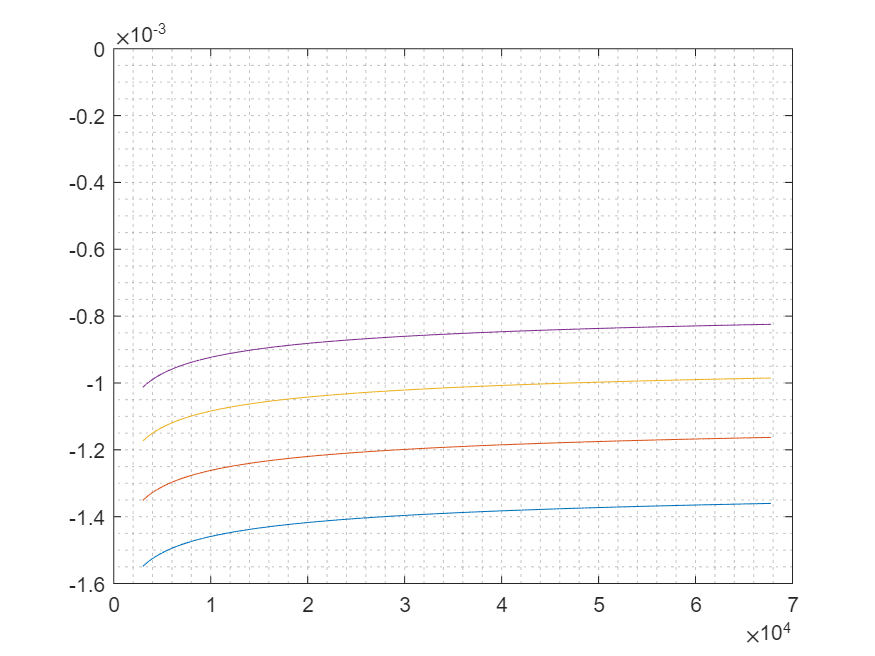


R = linspace(3000,67770,200);
Y0 = A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_0;
Y1 = A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_1;
Y2 = A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_2;
Y3 = A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_3;



plot(R, Y0)
hold on 
plot(R, Y1)
plot(R, Y2)
plot(R, Y3)
yline(0)
grid('minor')
hold off

% Y = A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_0 +...
%     A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_1 +...
%     A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_2 +...
%     A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_3;
R = 10000

R = 10000

T_0 = 1/(A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3);
T_0_ = vpa(T_0 -273.15,3)

$$T\_0\_ = 167.0$$



syms R
Y = A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_0 +...
    A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_1 +...
    A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_2 +...
    A0 + A1 * log(R) +  A2 * log(R).^2 + A3 * log(R).^3 - 1/T_3;

vpasolve(Y == 0.001, R)

 
ans =
 
Empty sym: 0-by-1
 


plot(R, Y)

Error using plot
Data must be numeric, datetime, duration or an array convertible to double.

yline(0)
grid('minor')
